# Make cancer cell line models

Author: Scott Campit

## Summary

This module computes metabolic fluxes for several histone post-translational modification related demand reaction from a constrained eGEMM model using the [CCLE RNASeq](https://www.ebi.ac.uk/gxa/experiments/E-MTAB-2770/Results) data from [Barretina et al., 2012](https://www.nature.com/articles/nature11003). 

## 1. Initialize COBRA

Below are several preprocessig steps, including:

- Setting biomass objective function

- Lowering methionine substrate uptake rate 

- Setting up params for iMAT (default settings used with pFBA)

- Assigning the activity through demand reactions to be 0.0625. based on a previous analysis with nutrient supplementation and deprivation.

% Initialize metabolic modeling components
clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all');



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

## 2. Load metabolic models

This code block loads specific versions of the eGEMM.

%load ~/Data/Reconstructions/eGEM/07132020.mat; % Contains all reactions, including demethylation and deacetylation reactions
load ~/Data/Reconstructions/eGEM/09072020_write_only.mat

Set the objective function to maximize biomass

% Set up objective function
eGEM.c = zeros(size(eGEM.c));
eGEM.c(string(eGEM.rxns) == 'biomass_objective') = 1;

Set the lower bound for methionine uptake

% Set methionine lower bound to a really small number
[~, pos] = ismember({'EX_met_L_e'}, eGEM.rxns);
eGEM.lb(pos) = -1;

Let's turn off some specific reactions that cause trouble with metabolic models.

% Turn off specific reactions
posToTurnOff           = find(ismember(eGEM.rxns, {'ALR', 'MGSA', 'MGSA2'}));
eGEM.ub(posToTurnOff) = 0; eGEM.lb(posToTurnOff) = 0;

Assign values of parameters for the iMAT algorithm.

% Set up hyperparameters for the linear programming section
hyperparams.eps = []; hyperparams.isgenes = true;
hyperparams.kap = []; hyperparams.eps2 = [];
hyperparams.rho = []; hyperparams.pfba = false;
hyperparams.kap2 = [];

Set the activity coefficient for demand reactions to be a fixed value, based on the medium perturbation experiments I ran with this current iteration of the eGEMM.

% Get list of demand reactions from eGEMM
%pos = [3773:3777]; % Bulk reactions only
pos = [3773:3777, 3780:3799];
dm_reactions = string(eGEM.rxns(pos))'

dm_reactions = 1×25 string array
    "DM_KACn"    "DM_KACc"    "DM_KMe1"    "DM_KMe2"    "DM_KMe3"    "DM_h3k4me1_n"    "DM_h3k4me2_n"    "DM_h3k4me3_n"    "DM_h3k4ac1_n"    "DM_h3k9me1_n"    "DM_h3k9me2_n"    "DM_h3k9me3_n"    "DM_h3k9ac1_n"    "DM_h3k27me1_n"    "DM_h3k27me2_n"    "DM_h3k27me3_n"    "DM_h3k27ac1_n"    "DM_h3k36me1_n"    "DM_h3k36me2_n"    "DM_h3k36me3_n"    "DM_h3k36ac1_n"    "DM_h3k79me1_n"    "DM_h3k79me2_n"    "DM_h3k79me3_n"    "DM_h3k79ac1_n"


% Activity coefficient for demand reactions
epsilon_methylation = 0.069;
epsilon_acetylation = 0.069;
for i = 1:length(dm_reactions)
    if contains(lower(dm_reactions(i)), "ac")
        epsilon(i, 1) = epsilon_acetylation;
    else
        epsilon(i, 1) = epsilon_methylation;
    end
end

## 3. Compute base metabolic model fluxes and growth rates for comparison

Compute the solution

for i = 1:length(dm_reactions)
    [~, rxnPos] = ismember(dm_reactions(i), eGEM.rxns);
    
    % Add activity to demand reactions
    tmp = eGEM;
    tmp.c(rxnPos) = epsilon(i);
    
    [~, soln] = CFR(tmp, hyperparams, {}, {});
    
    grate(1, i) = soln.x(3743);

    tmp2 = tmp;
    tmp2.lb(3743) = soln.x(3743) * 0.99;
    tmp2.c(3743)  = 0;                                                
    
    [~, soln] = CFR(tmp, hyperparams, {}, {});
    flux(1, i)  = soln.x(rxnPos);
end

## 4. Preprocess Cancer Cell Line Encyclopedia data

### Load data from the Cancer Cell Line Encyclopedia

This module uses RNASeq data from the CCLE and performs some basic preprocessing. The data was normalized to TPM. There are 864 cancer cell lines by 1020 metabolic genes that map onto RECON1 using Entrez identifiers.

load ~/Data/RNASeq/CCLE/CCLE_RNASeq.mat
load ~/Data/Proteomics/CCLE/CCLE_Proteomics.mat

[~, ia, ib] = intersect(cell_lines, string(cell_names));
cell_lines = cell_lines(ia);
cell_names = cell_names(ib);

log2fc = log2fc(:, ia);
pvalue = pvalue(:, ia);

proteomics = proteomics(ib, :);
medium = medium(ib);
cultures = cultures(ib);
tissues = tissues(ib);

## 5. Compute CCLE metabolic fluxes from the eGEMM

### All reactions

Because MATLAB has been crashing on me, we will save the file iteratively in the for loop.

fileName = '~/Data/CBM/eGEM/CCLE_fluxes_09072020_writers_only.mat';
save(fileName, '-v7.3')
entrez_ids = entrez_ids + '.1';

Now let's compute the data using the model. The data will automatically be saved.

% Demand reactions
flux = {};
for i = 1:length(dm_reactions)
    [~, rxnPos] = ismember(dm_reactions(i), eGEM.rxns);
    tmp = eGEM;
    tmp.c(rxnPos) = epsilon(i);
    
    % Cell lines
    for j = 1:size(log2fc, 2)
        
        % Get differentially expressed genes for each cancer cell line.
        DE{j}.name    = cell_names(j);
        DE{j}.medium  = medium(j);
        DE{j}.culture = cultures(j);
        DE{j}.tissue  = tissues(j);
        DE{j}.upreg   = entrez_ids(log2fc(:, j) > 0 & pvalue(:, j) <= 0.05);
        DE{j}.downreg = entrez_ids(log2fc(:, j) < 0 & pvalue(:, j) <= 0.05);
        
        % Constrain the metabolic model to be medium-specific
        mediumModel = addMediumConstraints(tmp, medium(j));
        
        % We're not perfect
        try
            % Compute flux using iMAT 
            [mdl, soln] = CFR(mediumModel, hyperparams, ...
                              DE{j}.upreg, DE{j}.downreg);
                                           
            % Get the growth rate
            grate(i, j) = soln.x(3743);
            
            % Ensure there's growth
            tmp2 = mediumModel;
            tmp2.lb(3743) = soln.x(3743) * 0.99;
            tmp2.c(3743)  = 0;                                                
            
            % Compute metabolic flux when optimizing histone markers
            [~, soln] = CFR(tmp2, hyperparams, DE{j}.upreg, DE{j}.downreg);
    
            % Store data here
            flux{i, j} = soln.x(1:length(eGEM.rxns));
            
        catch ME
            flux{i, j} = NaN;
            grate(i, j) = NaN;
        end
        
        save(fileName, 'flux', 'grate', 'j', 'i', '-append');
        
    end
end

### Writers only

For this scheme, I need to separate the RNASeq data out by whether or not the differentially expressed genes are writers or erasers. Then, I need to create a scaling factor for the upper bound that is proportional to the ratio of writers over erasers. So if I have a large number of erasers, the upper bound will be small, and will minimize flux. Otherwise, the reaction will have a larger upper bound value.

First, let's get gene identifiers that are associated with histone writers and erasers.

histone_mod_entrez = readcell();


Then we can compute the metabolic fluxes.

% Demand reactions
flux = {};
for i = 1:length(dm_reactions)
    
    % Set the objective coefficient for the model to be 0.069.
    [~, rxnPos] = ismember(dm_reactions(i), eGEM.rxns);
    tmp = eGEM;
    tmp.c(rxnPos) = epsilon(i);
    
    % Cell lines
    for j = 1:size(log2fc, 2)
        
        % Get differentially expressed genes for each cancer cell line.
        DE{j}.name    = cell_names(j);
        DE{j}.medium  = medium(j);
        DE{j}.culture = cultures(j);
        DE{j}.tissue  = tissues(j);
        DE{j}.upreg   = entrez_ids(log2fc(:, j) > 0 & pvalue(:, j) <= 0.05);
        DE{j}.downreg = entrez_ids(log2fc(:, j) < 0 & pvalue(:, j) <= 0.05);
        
        % Get writers and erasers
        histone_modifiers = [DE{j}.upreg, DE{j}.downreg]
        histone_modifiers = strrep(histone_modifiers, '.1', '');
        
        
        % Get writers and erasers that are upregulated
        
        % Get writers and erasers that are downregulated
        
        % Compute a score that reflects the proportion of up and
        % downregulated writers / erasers
        
        % Set the upper bound of the reaction to be scaled to this writer:eraser ratio
        
        % Constrain the metabolic model to be medium-specific
        mediumModel = addMediumConstraints(tmp, medium(j));
        
        % We're not perfect
        try
            % Compute flux using iMAT 
            [mdl, soln] = CFR(mediumModel, hyperparams, ...
                              DE{j}.upreg, DE{j}.downreg);
                                           
            % Get the growth rate
            grate(i, j) = soln.x(3743);

map = 12×4 string array
    "a549"        "Lung"                   "RPMI"    "Adherent"  
    "hct116"      "Large Intestine"        "DMEM"    "Empty"     
    "hl60"        "Skin"                   "EMEM"    "Adherent"  
    "huh7"        "Haematopoietic an…"    "DMEM"    "Empty"     
    "mcf7"        "Haematopoietic an…"    "RPMI"    "Adherent"  
    "mdamb231"    "Lung"                   "RPMI"    "Adherent"  
    "nb4"         "Kidney"                 "RPMI"    "Suspension"
    "panc1"       "Lung"                   "RPMI"    "Empty"     
    "pc3"         "Skin"                   "RPMI"    "Empty"     
    "sw480"       "Lung"                   "L15"     "Adherent"  
    "u2os"        "Kidney"                 "RPMI"    "Empty"     
    "u937"        "Pancreas"               "RPMI"    "Empty"     


            
            % Ensure there's growth
            tmp2 = mediumModel;
            tmp2.lb(3743) = soln.x(3743) * 0.99;
            tmp2.c(3743)  = 0;                                                
            
            % Compute metabolic flux when optimizing histone markers
            [~, soln] = CFR(tmp2, hyperparams, DE{j}.upreg, DE{j}.downreg);
    
            % Store data here
            flux{i, j} = soln.x(1:length(eGEM.rxns));
            
        catch ME
            flux{i, j} = NaN;
            grate(i, j) = NaN;
        end
        
        save(fileName, 'flux', 'grate', 'j', 'i', '-append');
        
    end
end

## LeRoy modeling

### Load gene expression data from the LeRoy dataset

This module uses RNASeq data from the CCLE RNASeq dataset, and maps it to intersecting cancer cell lines in the LeRoy cancer cell lines. Additional methods include some basic preprocessing. The data was normalized to TPM. 

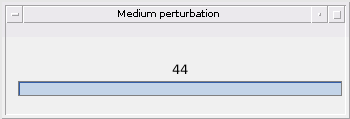

clearvars -except eGEM hyperparams epsilon

fileName = '/home/scampit/Data/Expression/RNASeq/CCLE/MappedRNASeq.xlsx';
df = readcell(fileName, 'Sheet', 'BiGG');

### Process gene expression data

This module stores necessary meta-data (`map`, `genes`) and performs some necessary data preprocessing, such as filling missing with NaN, and turns the data into a double.

% Get mapping data (Gene ID, Tissue, Culture, Medium)
map = string(df(2:end, 1:4));
df(:, 1:4) = [];

% LeRoy cell lines
load leroy.mat leroy_cellline
[~, idx, ~] = intersect(string(map(:, 1)), lower(string(leroy_cellline)));

% Get gene identifier
genes = df(1, :);
df(1, :) = [];

% Turn missing to NaN;
data = df;
mask = cellfun(@ismissing, data);
data(mask) = {NaN};

% Convert cell array to be a numerical array
new_data = cell2mat(data);

### Standardize Gene Expression Data

The data was standardize per gene to have mean equal 0 and standard deviation equal 1. The p-value was computed from a normal probability distribution function. 

Genes that had a p-value > 0.05 were masked to be NaN. Upregulated genes were encoded to have a value of 1. Downregulated genes were encoded to have a value of -1. This is partitioned later when computing cancer cell line specific metabolic fluxes.

% Standardize data by gene and get p-value
mu = nanmean(new_data, 1);
sigma = nanstd(new_data, [], 1);
Zdata = (new_data - mu) ./ sigma;
pvalue = normpdf(Zdata);
mask = Zdata;
mask(pvalue < 0.05) = NaN;

% Encode data
ids = eGEM.genes;
[~, ia, ib] = intersect(ids, genes);
final_df = mask(:, ib);
genes = genes(ib);
final_df(final_df > 0) = 1;
final_df(final_df < 0) = -1;

% Get LeRoy data specifically
map = map(idx, :);
final_df = final_df(idx, :);

% Clear data due to memory issues / MATLAB crashing
clear df data new_data mask Zdata 

### Compute wild-type metabolic fluxes from the eGEMM

First let's initialize the reactions we're interested in, as well as allocating some data objects to store the solutions in the for loop.

% Get list of demand reactions from eGEMM
pos = [3770, 3771, 3773:3814];
dm_reactions = string(eGEM.rxns(pos))';

% Initialize data arrays
DE = cell(size(final_df, 1), 1);
flux = zeros(length(dm_reactions), size(final_df, 1));
meta_data = cell(size(final_df, 1), length(dm_reactions));

Now let's compute the data using the model. The data will automatically be saved.

wtbr = waitbar(0, '0', 'Name', 'Medium perturbation'); 
% Medium perturbation
for i = 1:length(dm_reactions)
    for j = 1:size(final_df, 1)
        
        % Get differentially expressed genes for each cancer cell line.
        DE{j}.name    = upper(map(j, 1));
        DE{j}.medium  = map(j, 3);
        DE{j}.culture = map(j, 4);
        DE{j}.tissue  = map(j, 2);
        DE{j}.upreg   = genes(final_df(2, :) == 1);
        DE{j}.downreg = genes(final_df(2, :) == -1);
        upgenes = DE{j}.upreg;
        downgenes = DE{j}.downreg;
        
        % Constrain the metabolic model to be medium-specific
        mediumModel = addMediumConstraints(eGEM, map(j, 3));
        
        % Set the activity coefficient of the demand reaction of interest
        mediumModel.c(pos(i)) = epsilon;
        
        % Compute flux using iMAT 
        [ConstrainedModel, solution] = CFR(...
                                           mediumModel, hyperparams, ...
                                           DE{j}.upreg, DE{j}.downreg);
        
        % Store data here
        flux(i, j) = solution.x(pos(i));
        grate(i, j) = solution.x(3743);
        meta_data{j, i} = DE;
    end
    waitbar(i/length(dm_reactions), wtbr, sprintf('%d', i))
end
save('~/Data/CBM/eGEM/base/LeRoy_07142020.mat', '-v7.3')